ceiling= 500 ;    %height at which the plane cruise
V = 34;    %desired cruise velocity
w=160 ;    %estimated weight of UAV
W=w*9.81;
W_s= 400 ;  %wing loading in N/m^2
row=1.225;
sigma=(1-6.873*10^(-6)*ceiling)^4.26

sigma = 0.9854

L_D=10  %taken for now

L_D = 10

AR=3:1:9            %initial aspect ratio

AR =      3     4     5     6     7     8     9


TR=0.1:0.1:0.9

TR =     0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000


n=length(AR)

n = 7

m=length(TR)

m = 9

s=W/W_s

s = 3.9240

Cl_des=zeros(n,m);cr=zeros(n,m);b=zeros(n,m);ct=zeros(n,m);Cd_des=zeros(n,m);Cd_0=zeros(n,m);

e=1.78*(1- 0.045*AR.^0.68)-0.64;
k=1./(pi*e.*AR);
for i=1:n
    for j=1:m
    b(i,j)=sqrt(AR(i)*s);
    cr(i,j)= 2*s/(b(i,j)*(1+TR(j)));
    ct(i,j)=cr(i,j)*TR(j);
    
    Cl_des(i,j) = 2*W_s/(row*sigma*V^2); 
    Cd_des(i,j) = Cl_des(i,j)/L_D;
    Cd_0(i)=Cd_des(i,j)-k(i)*Cl_des(i,j);
    
    end
end
Cl_des

Cl_des =     0.5733    0.5733    0.5733    0.5733    0.5733    0.5733    0.5733    0.5733    0.5733
    0.5733    0.5733    0.5733    0.5733    0.5733    0.5733    0.5733    0.5733    0.5733
    0.5733    0.5733    0.5733    0.5733    0.5733    0.5733    0.5733    0.5733    0.5733
    0.5733    0.5733    0.5733    0.5733    0.5733    0.5733    0.5733    0.5733    0.5733
    0.5733    0.5733    0.5733    0.5733    0.5733    0.5733    0.5733    0.5733    0.5733
    0.5733    0.5733    0.5733    0.5733    0.5733    0.5733    0.5733    0.5733    0.5733
    0.5733    0.5733    0.5733    0.5733    0.5733    0.5733    0.5733    0.5733    0.5733


Cd_des

Cd_des =     0.0573    0.0573    0.0573    0.0573    0.0573    0.0573    0.0573    0.0573    0.0573
    0.0573    0.0573    0.0573    0.0573    0.0573    0.0573    0.0573    0.0573    0.0573
    0.0573    0.0573    0.0573    0.0573    0.0573    0.0573    0.0573    0.0573    0.0573
    0.0573    0.0573    0.0573    0.0573    0.0573    0.0573    0.0573    0.0573    0.0573
    0.0573    0.0573    0.0573    0.0573    0.0573    0.0573    0.0573    0.0573    0.0573
    0.0573    0.0573    0.0573    0.0573    0.0573    0.0573    0.0573    0.0573    0.0573
    0.0573    0.0573    0.0573    0.0573    0.0573    0.0573    0.0573    0.0573    0.0573


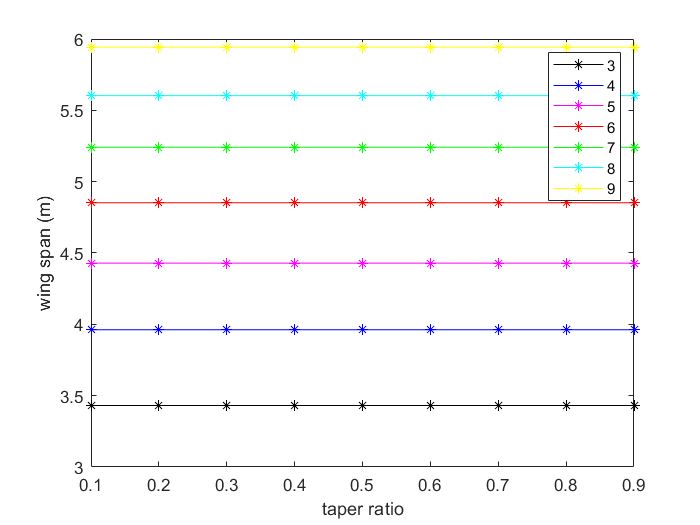

color=["k","b","m","r","g","c","y"];
A_R=string(AR);
for i=1:n
    plot(TR,b(i,:),"Color",color(i),"Marker","*")
    hold on
end
legend(A_R)
xlabel("taper ratio")
ylabel("wing span (m)")
hold off

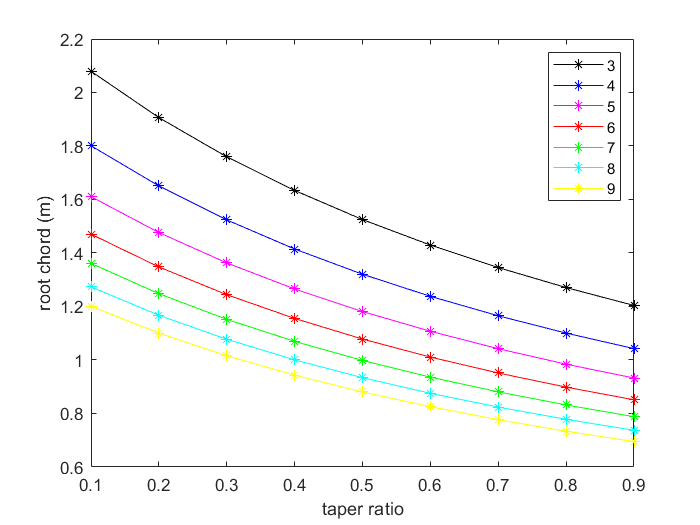


for i=1:n
    plot(TR,cr(i,:),"Color",color(i),"Marker","*")
    hold on
end
legend(A_R)
xlabel("taper ratio")
ylabel("root chord (m)")
hold off

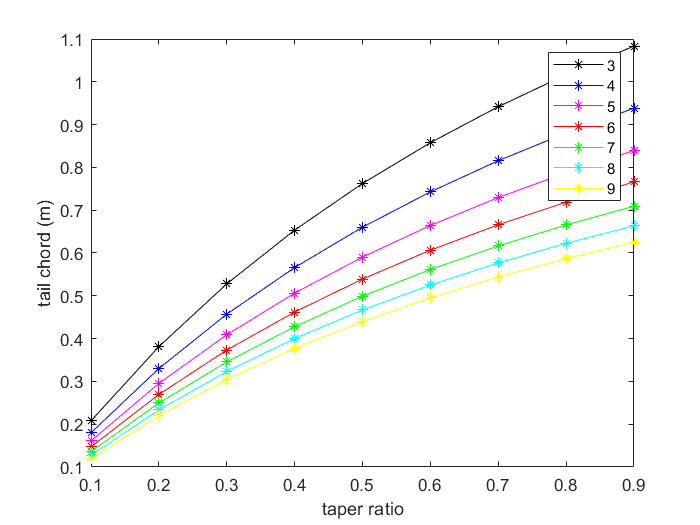


for i=1:n
    plot(TR,ct(i,:),"Color",color(i),"Marker","*")
    hold on
end
legend(A_R)
xlabel("taper ratio")
ylabel("tail chord (m)")
hold off